# ASEN 3128 Homework 3

#### William Watkins and Ponder Stine

## Problem 2.a

### Set up the Workspace

close all;
clear all;
clc;

### Declare Constants

global g I_x I_y I_z m R G_body g_body fb

g = 9.81; % [m/s^2], acceleration of gravity
m = 0.068; % [kg], mass of the quadcopter
R = 0.060; % [m], distance from CG to motors
I_x = 6.8 * 10 ^ (-5); % [kg*m^2], moment of inertia about x-axis
I_y = 9.2 * 10 ^ (-5); % [kg*m^2], moment of inertia about y-axis
I_z = 1.35 * 10 ^ (-4); % [kg*m^2], moment of inertia about z-axis
eta = 1 * 10 ^ (-3); % [N/(m/s)^2], drag per velocity squared
alpha = 2 * 10 ^ (-6); % [N*m/(rad/s)^2], moment per rate of rotation squared
k = 0.0024; % [N*m/N], moment per force of motors

### Initialize variables

x = 0; % [m], initial North position
y = 0; % [m], initial East position
z = -5; % [m], initial Down position
inertialVelocity = [0; 0; 0];
psi = 0;
theta = 0;
phi = deg2rad(5);
p = 0;
q = 0;
r = 0;

### Create and Apply Transformation Matrix

L_EB = [cos(theta) * cos(psi), sin(phi) * sin(theta) * cos(psi) - cos(phi) * sin(psi), cos(phi) * sin(theta) * cos(psi) + sin(phi) * sin(psi); ...
        cos(theta) * sin(psi), sin(phi) * sin(theta) * sin(psi) + cos(phi) * cos(psi), cos(phi) * sin(theta) * sin(psi) - sin(phi) * cos(psi); ...
        -sin(theta),           sin(phi) * cos(theta),                                  cos(phi) * cos(theta)];
L_BE = inv(L_EB);
g_body = L_BE * [0; 0; 9.81];
bodyVelocity = L_BE * inertialVelocity;
u = bodyVelocity(1);
v = bodyVelocity(2);
w = bodyVelocity(3);

### Preparing for the ODE45

initialState = [x y z p q r psi phi theta u v w];
tSpan = [0 10];

### Calling ODE 45

[t,y] = ode45('quadcopterSimulation', tSpan, initialState);
[tlin,ylin] = ode45('quadcopterSimulationLin', tSpan, initialState);

### Plotting the results

bodyVelocityFinal = [y(10); y(11); y(12)];
inertialVelocityFinal = L_EB * bodyVelocityFinal;
y(10) = inertialVelocityFinal(1);
y(11) = inertialVelocityFinal(2);
y(12) = inertialVelocityFinal(3);
bodyVelocityFinal = [ylin(10); ylin(11); ylin(12)];
inertialVelocityFinal = L_EB * bodyVelocityFinal;
ylin(10) = inertialVelocityFinal(1);
ylin(11) = inertialVelocityFinal(2);
ylin(12) = inertialVelocityFinal(3);

### +5 Degree Deviation in Bank

Non Linearized

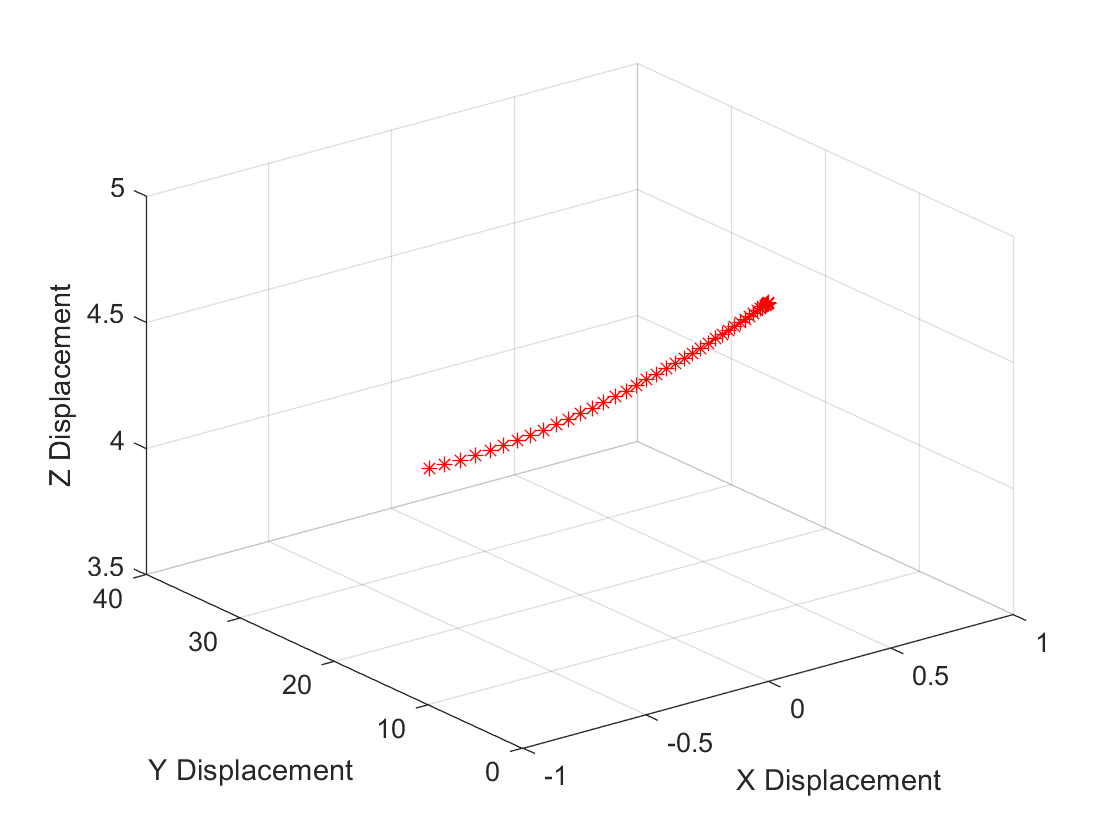

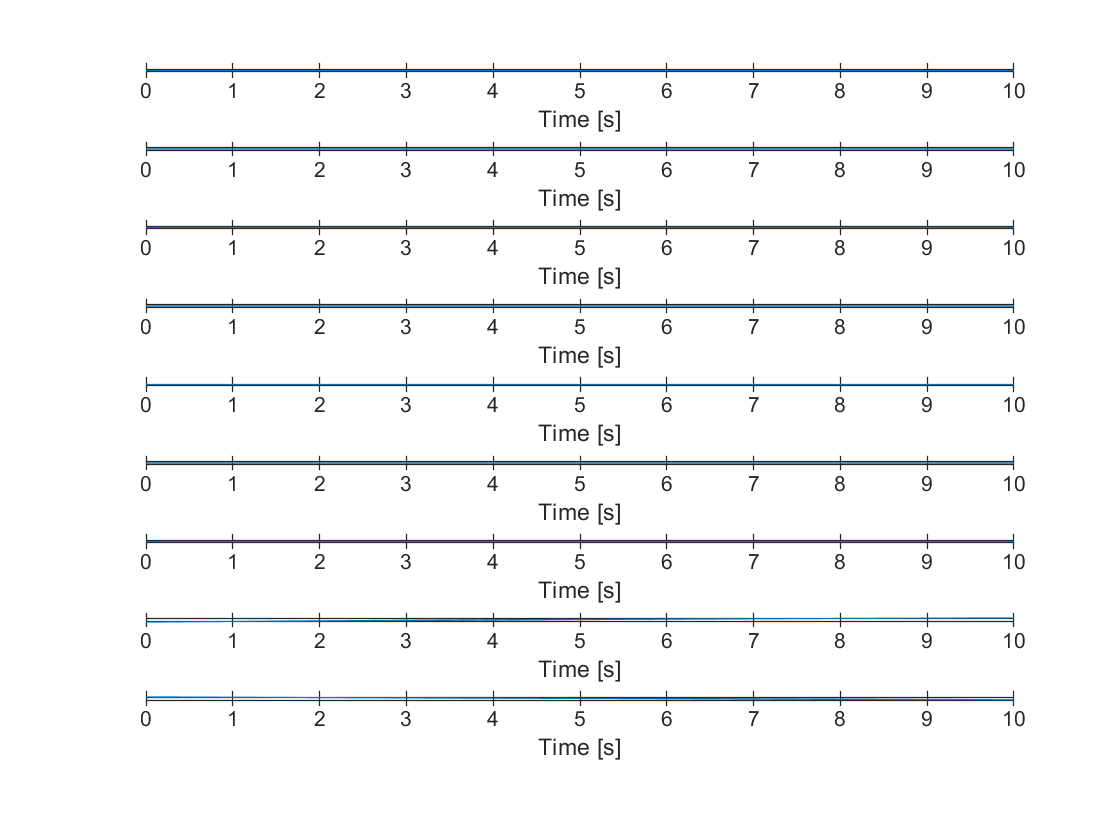

plotMotionNonLin(t,y);

Linearized

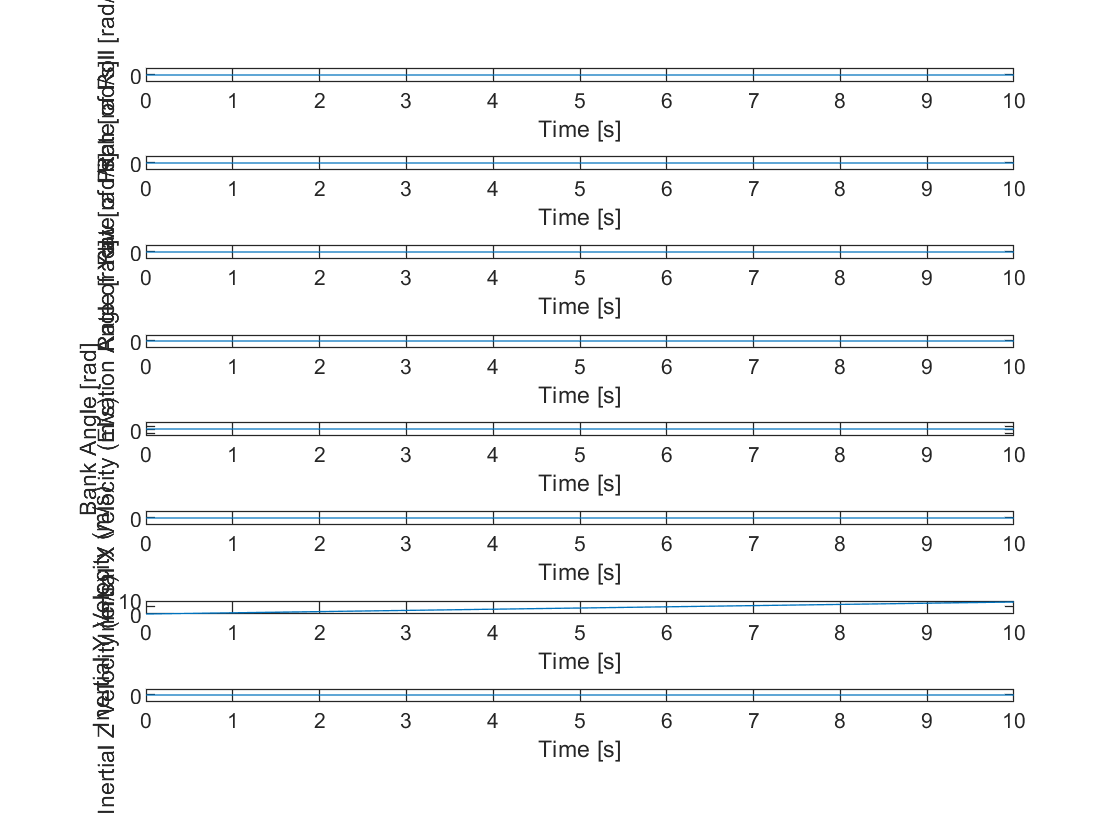

plotMotionLin(tlin, ylin);

## Problem 2.b

### Initialize variables

x = 0; % [m], initial North position
y = 0; % [m], initial East position
z = -5; % [m], initial Down position
inertialVelocity = [0; 0; 0];
psi = 0;
theta = deg2rad(5);
phi = 0;
p = 0;
q = 0;
r = 0;

### Create and Apply Transformation Matrix

L_EB = [cos(theta) * cos(psi), sin(phi) * sin(theta) * cos(psi) - cos(phi) * sin(psi), cos(phi) * sin(theta) * cos(psi) + sin(phi) * sin(psi); ...
        cos(theta) * sin(psi), sin(phi) * sin(theta) * sin(psi) + cos(phi) * cos(psi), cos(phi) * sin(theta) * sin(psi) - sin(phi) * cos(psi); ...
        -sin(theta),           sin(phi) * cos(theta),                                  cos(phi) * cos(theta)];
L_BE = inv(L_EB);
g_body = L_BE * [0; 0; 9.81];
bodyVelocity2 = L_BE * inertialVelocity;
u = bodyVelocity2(1);
v = bodyVelocity2(2);
w = bodyVelocity2(3);

### Preparing for the ODE45

initialState2 = [x y z p q r psi phi theta u v w];
tSpan = [0 10];

### Calling ODE 45

[t2,y2] = ode45('quadcopterSimulation', tSpan, initialState2);
[tlin2,ylin2] = ode45('quadcopterSimulationLin', tSpan, initialState2);

### Plotting the results

bodyVelocityFinal = [y2(10); y2(11); y2(12)];
inertialVelocityFinal = L_EB * bodyVelocityFinal;
y2(10) = inertialVelocityFinal(1);
y2(11) = inertialVelocityFinal(2);
y2(12) = inertialVelocityFinal(3);
bodyVelocityFinal = [ylin2(10); ylin2(11); ylin2(12)];
inertialVelocityFinal = L_EB * bodyVelocityFinal;
ylin2(10) = inertialVelocityFinal(1);
ylin2(11) = inertialVelocityFinal(2);
ylin2(12) = inertialVelocityFinal(3);

### +5 Degree Deviation in Pitch

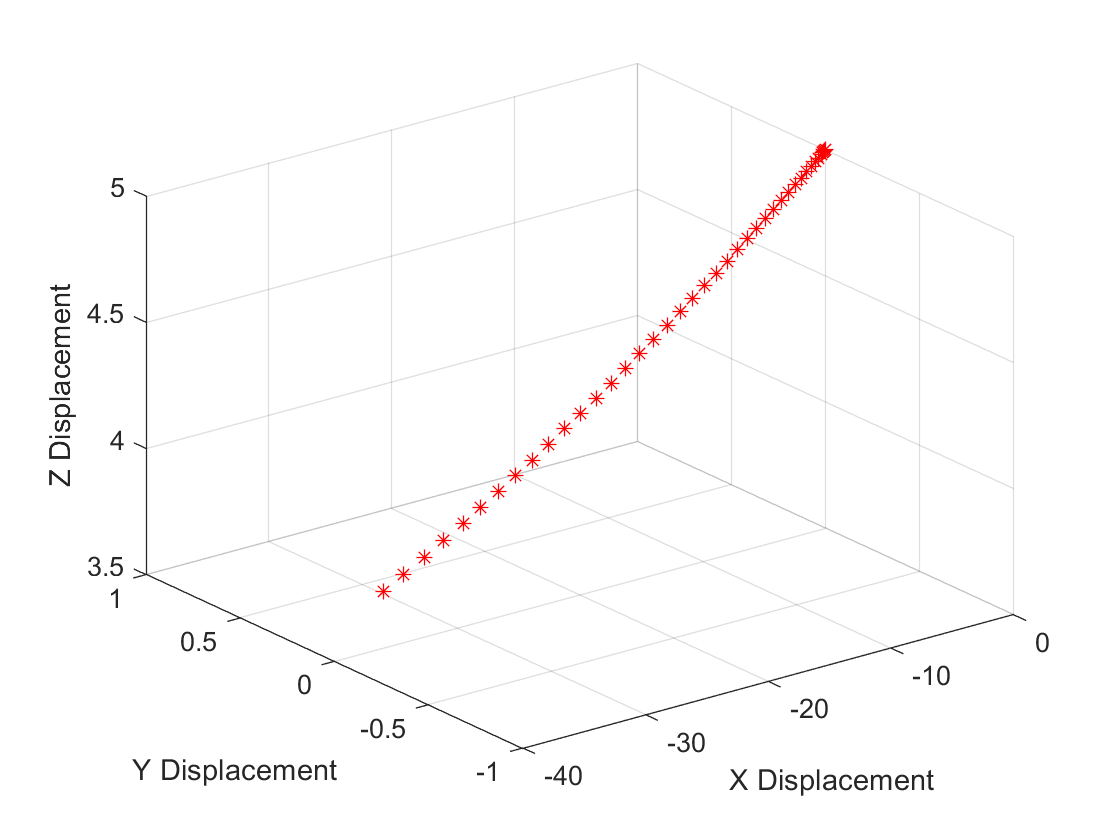

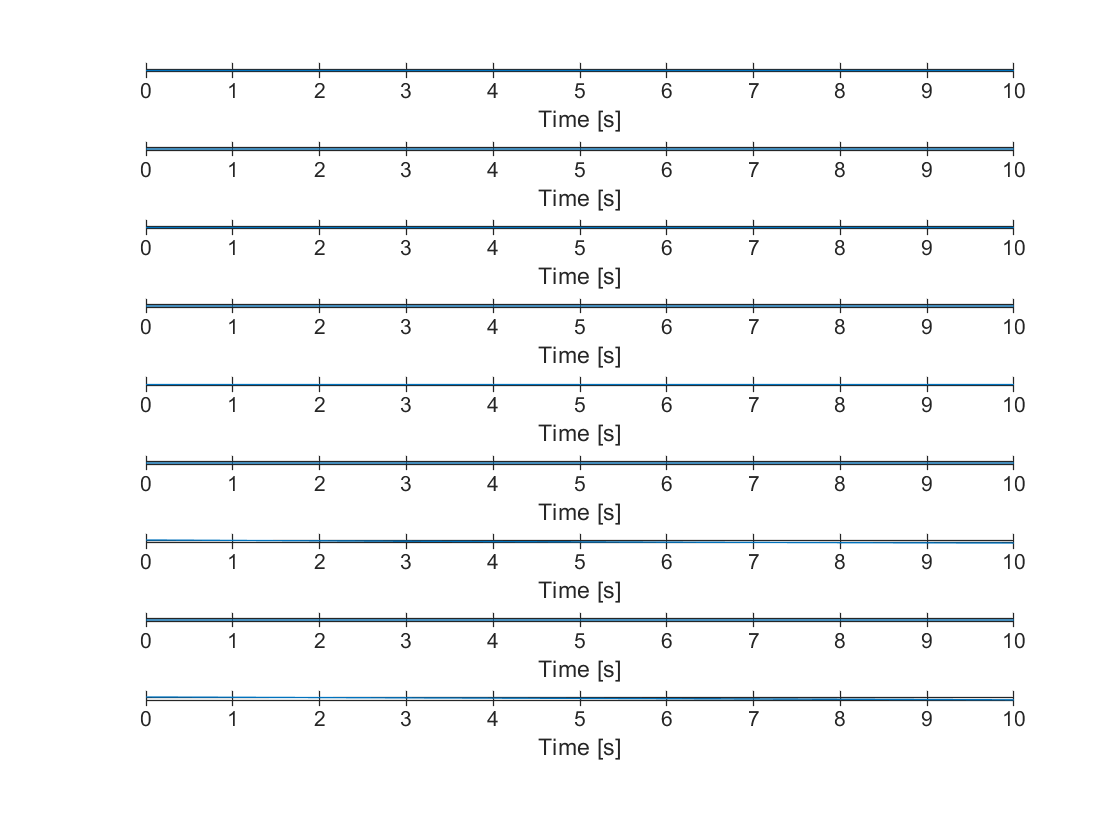

plotMotionNonLin(t2,y2);

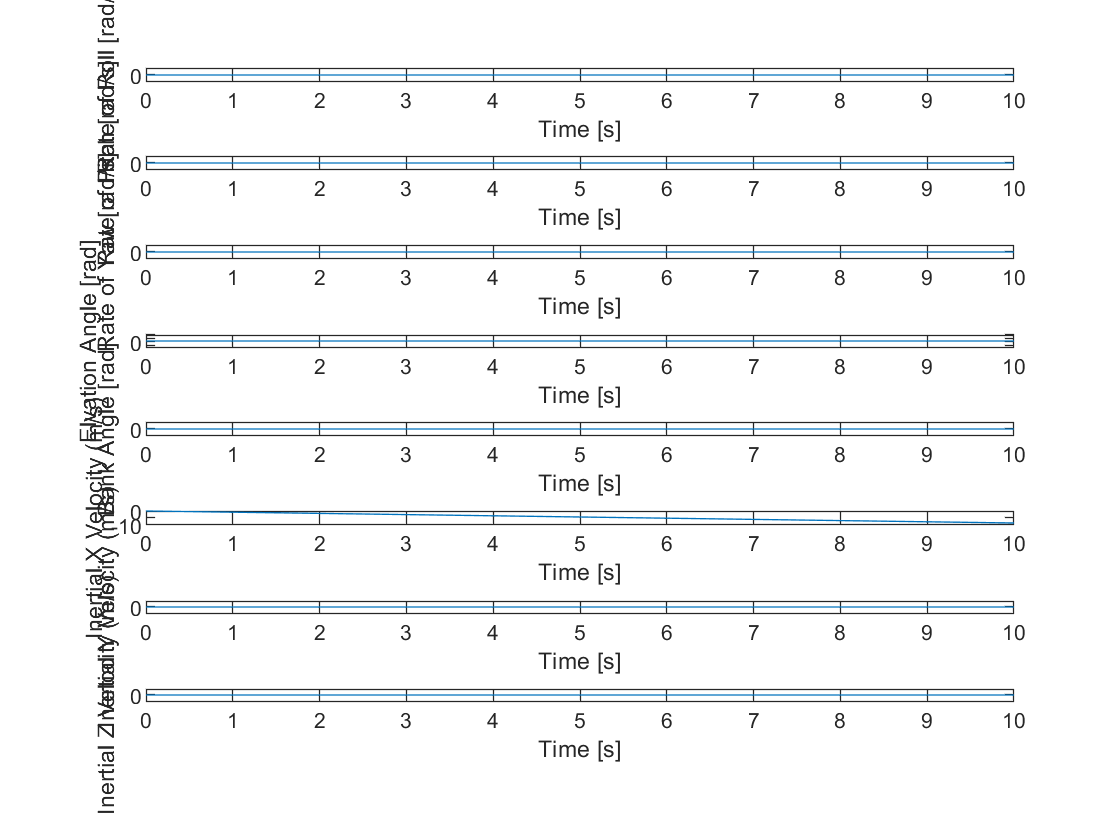

plotMotionLin(tlin2, ylin2);

## Problem 2.c

### Initialize variables

x = 0; % [m], initial North position
y = 0; % [m], initial East position
z = -5; % [m], initial Down position
inertialVelocity = [0; 0; 0];
psi = 5 * pi / 180;
theta = 0;
phi = 0;
p = 0;
q = 0;
r = 0;

### Create and Apply Transformation Matrix

L_EB = [cos(theta) * cos(psi), sin(phi) * sin(theta) * cos(psi) - cos(phi) * sin(psi), cos(phi) * sin(theta) * cos(psi) + sin(phi) * sin(psi); ...
        cos(theta) * sin(psi), sin(phi) * sin(theta) * sin(psi) + cos(phi) * cos(psi), cos(phi) * sin(theta) * sin(psi) - sin(phi) * cos(psi); ...
        -sin(theta),           sin(phi) * cos(theta),                                  cos(phi) * cos(theta)];
L_BE = inv(L_EB);
g_body = L_BE * [0; 0; 9.81];
bodyVelocity3 = L_BE * inertialVelocity;
u = bodyVelocity3(1);
v = bodyVelocity3(2);
w = bodyVelocity3(3);

### Preparing for the ODE45

initialState3 = [x y z p q r psi phi theta u v w];
tSpan = [0 10];

### Calling ODE 45

[t3,y3] = ode45('quadcopterSimulation', tSpan, initialState3);
[tlin3,ylin3] = ode45('quadcopterSimulationLin', tSpan, initialState3);

### Plotting the results

bodyVelocityFinal = [y3(10); y3(11); y3(12)];
inertialVelocityFinal = L_EB * bodyVelocityFinal;
y3(10) = inertialVelocityFinal(1);
y3(11) = inertialVelocityFinal(2);
y3(12) = inertialVelocityFinal(3);
bodyVelocityFinal = [ylin3(10); ylin3(11); ylin3(12)];
inertialVelocityFinal = L_EB * bodyVelocityFinal;
ylin3(10) = inertialVelocityFinal(1);
ylin3(11) = inertialVelocityFinal(2);
ylin3(12) = inertialVelocityFinal(3);

### +5 Degree Deviation in Azimuth

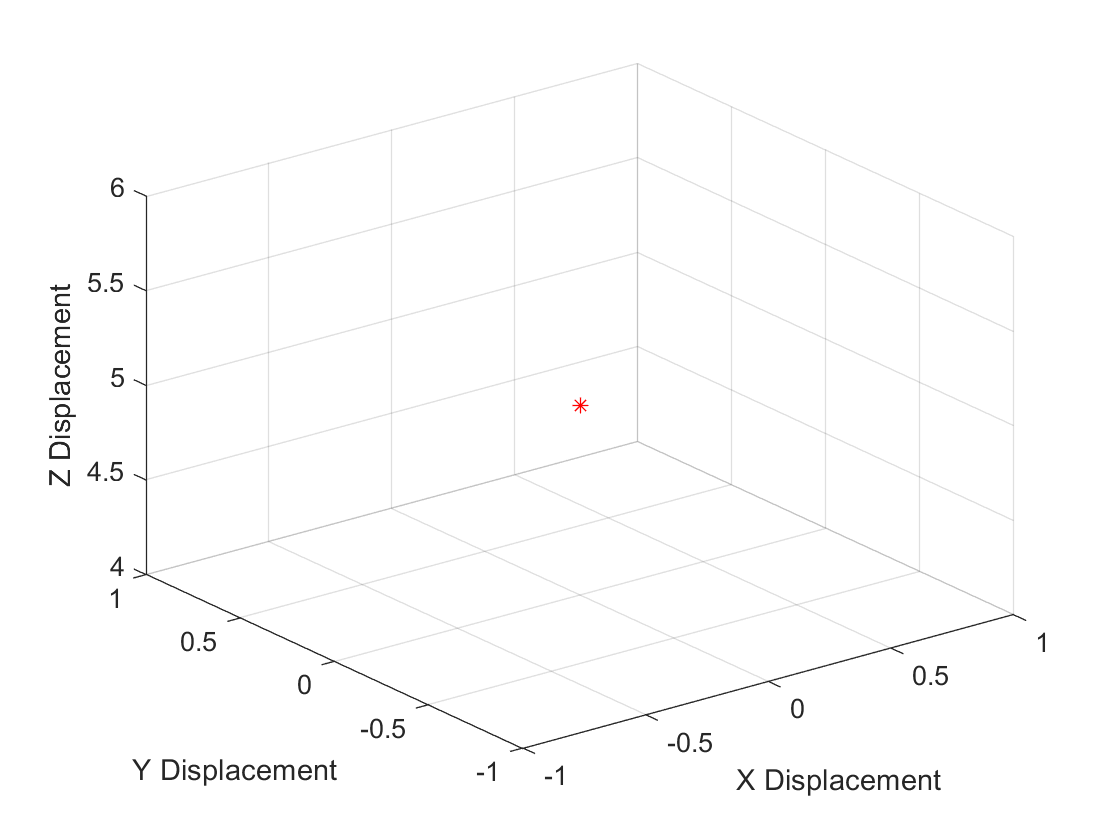

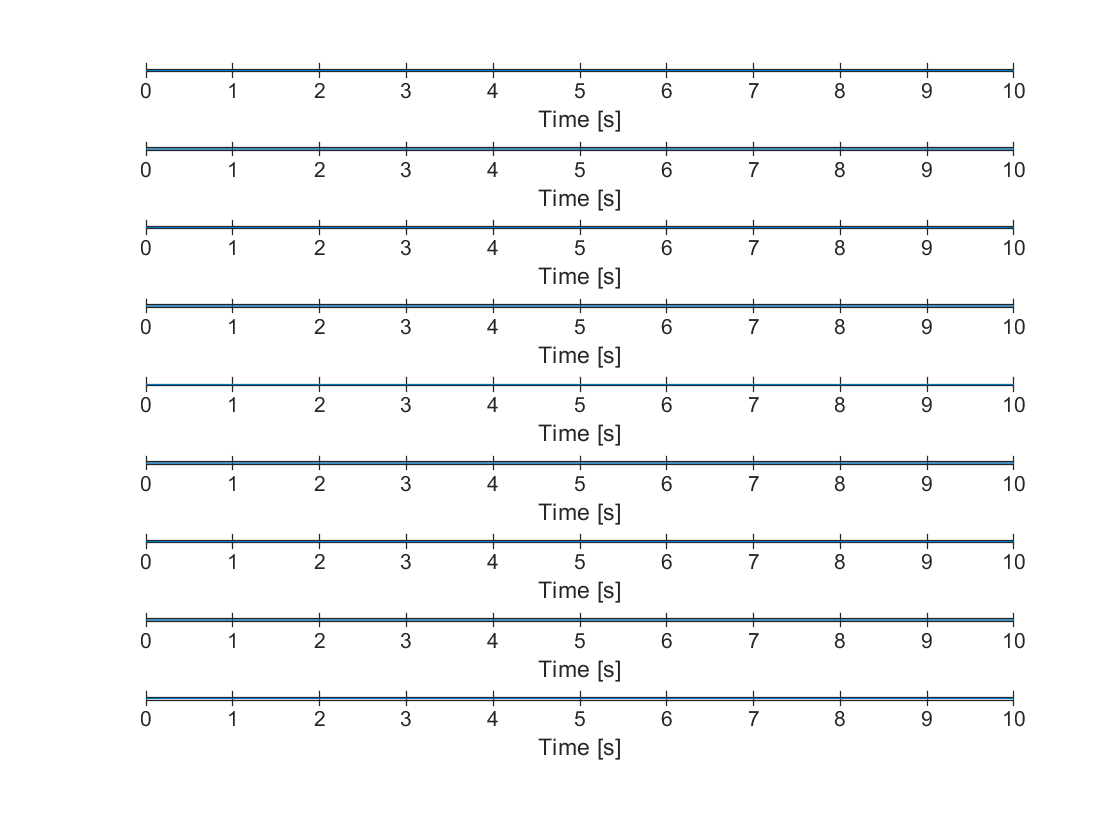

plotMotionNonLin(t3,y3);

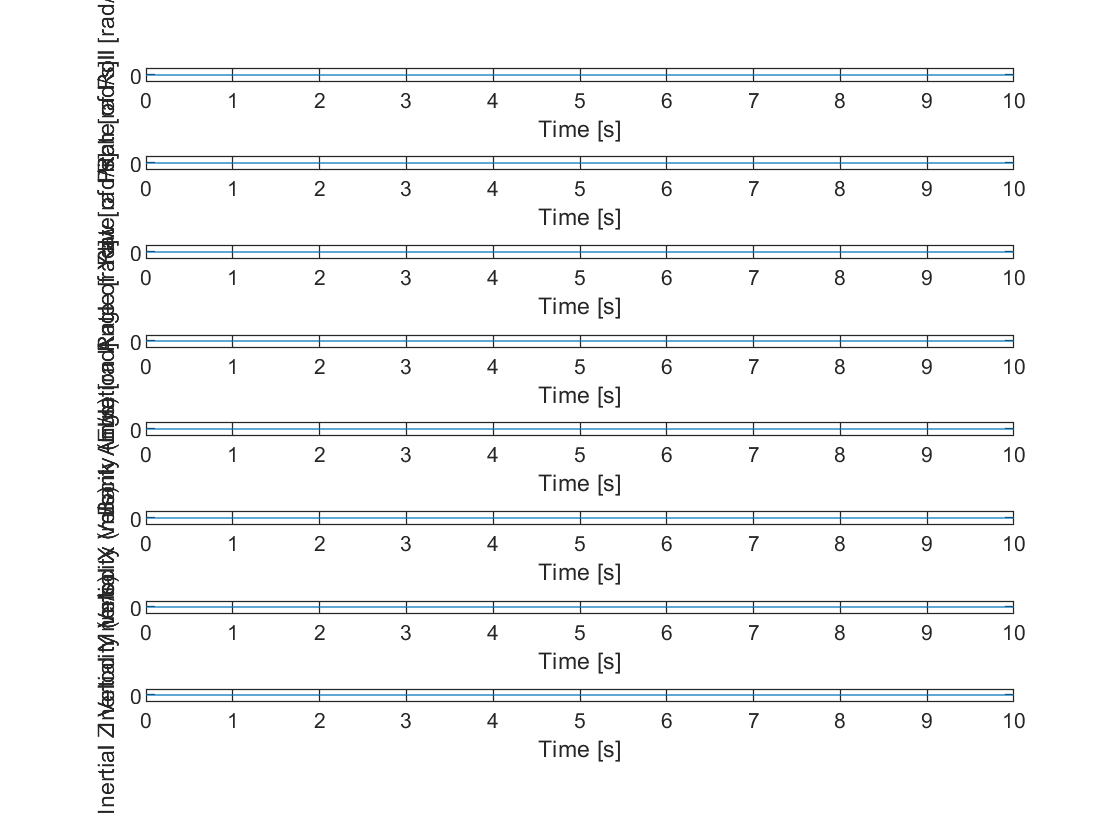

plotMotionLin(tlin3, ylin3);

## Problem 2.d

### Initialize variables

x = 0; % [m], initial North position
y = 0; % [m], initial East position
z = -5; % [m], initial Down position
inertialVelocity = [0; 0; 0];
psi = 0;
theta = 0;
phi = 0;
p = 0.1;
q = 0;
r = 0;

### Create and Apply Transformation Matrix

L_EB = [cos(theta) * cos(psi), sin(phi) * sin(theta) * cos(psi) - cos(phi) * sin(psi), cos(phi) * sin(theta) * cos(psi) + sin(phi) * sin(psi); ...
        cos(theta) * sin(psi), sin(phi) * sin(theta) * sin(psi) + cos(phi) * cos(psi), cos(phi) * sin(theta) * sin(psi) - sin(phi) * cos(psi); ...
        -sin(theta),           sin(phi) * cos(theta),                                  cos(phi) * cos(theta)];
L_BE = inv(L_EB);
g_body = L_BE * [0; 0; 9.81];
bodyVelocity4 = L_BE * inertialVelocity;
u = bodyVelocity4(1);
v = bodyVelocity4(2);
w = bodyVelocity4(3);

### Preparing for the ODE45

initialState4 = [x y z p q r psi phi theta u v w];
tSpan = [0 10];

### Calling ODE 45

[t4,y4] = ode45('quadcopterSimulation', tSpan, initialState4);
[tlin4,ylin4] = ode45('quadcopterSimulationLin', tSpan, initialState4);
[t4F,y4F] = ode45('quadcopterSimulationNonLinFC', tSpan, initialState4);

### Plotting the results

bodyVelocityFinal = [y4(10); y4(11); y4(12)];
inertialVelocityFinal = L_EB * bodyVelocityFinal;
y4(10) = inertialVelocityFinal(1);
y4(11) = inertialVelocityFinal(2);
y4(12) = inertialVelocityFinal(3);
bodyVelocityFinal = [ylin4(10); ylin4(11); ylin4(12)];
inertialVelocityFinal = L_EB * bodyVelocityFinal;
ylin4(10) = inertialVelocityFinal(1);
ylin4(11) = inertialVelocityFinal(2);
ylin4(12) = inertialVelocityFinal(3);
bodyVelocityFinal = [y4F(10); y4F(11); y4F(12)];
inertialVelocityFinal = L_EB * bodyVelocityFinal;
y4F(10) = inertialVelocityFinal(1);
y4F(11) = inertialVelocityFinal(2);
y4F(12) = inertialVelocityFinal(3);

### +0.1 rad/s Roll Rate Deviation

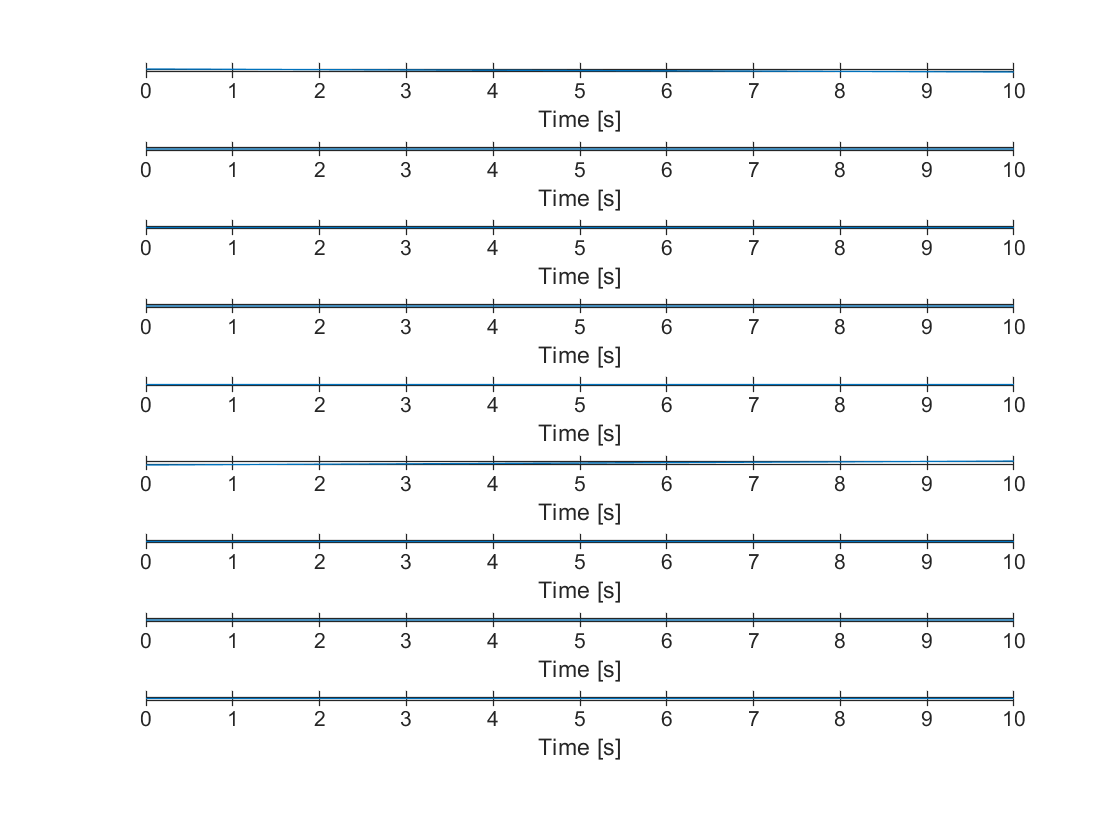

plotMotionNonLin(t4,y4);

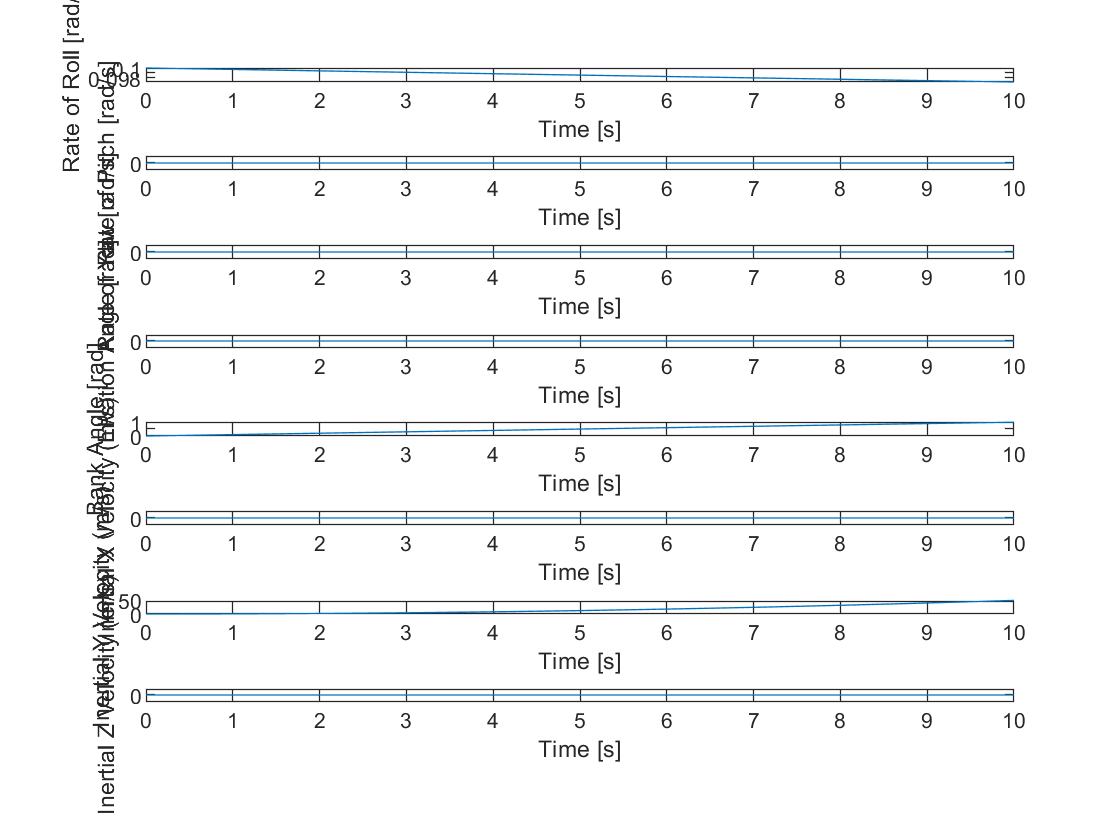

plotMotionLin(tlin4, ylin4);

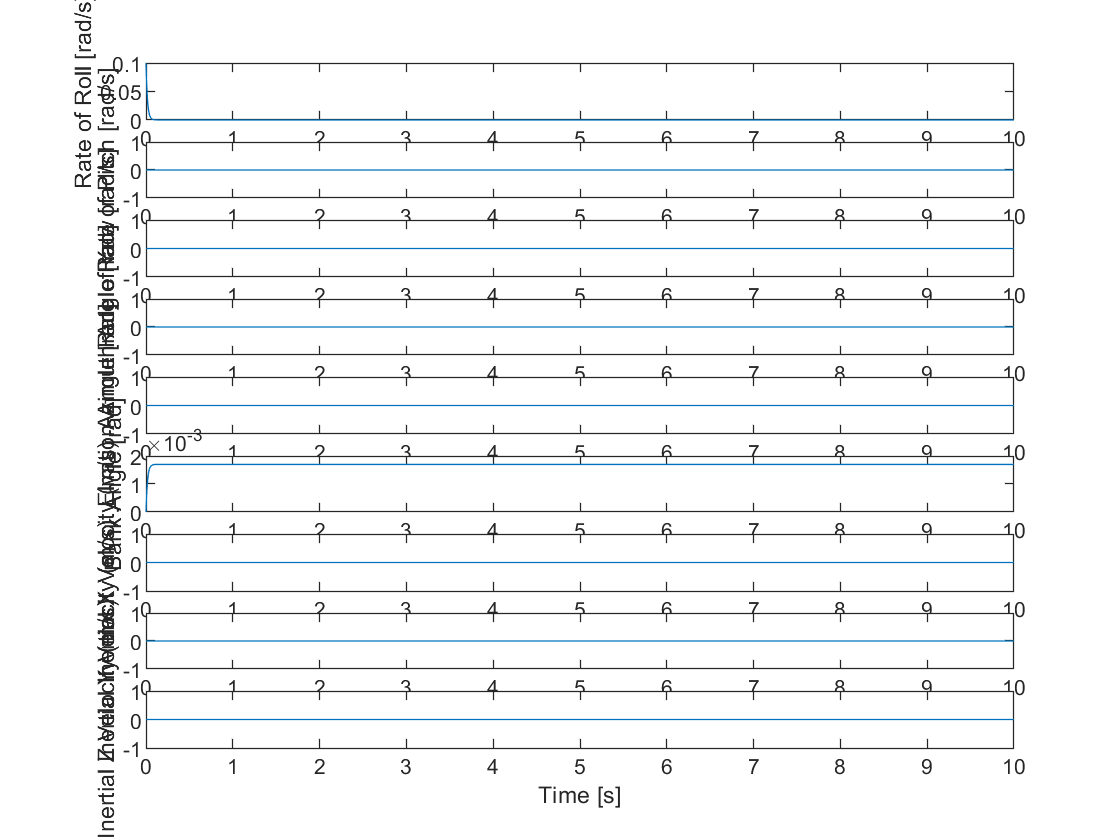

plotMotionNonLin(t4F,y4F);

## Problem 2.e

### Initialize variables

x = 0; % [m], initial North position
y = 0; % [m], initial East position
z = -5; % [m], initial Down position
inertialVelocity = [0; 0; 0];
psi = 0;
theta = 0;
phi = 0;
p = 0;
q = 0.1;
r = 0;

### Create and Apply Transformation Matrix

L_EB = [cos(theta) * cos(psi), sin(phi) * sin(theta) * cos(psi) - cos(phi) * sin(psi), cos(phi) * sin(theta) * cos(psi) + sin(phi) * sin(psi); ...
        cos(theta) * sin(psi), sin(phi) * sin(theta) * sin(psi) + cos(phi) * cos(psi), cos(phi) * sin(theta) * sin(psi) - sin(phi) * cos(psi); ...
        -sin(theta),           sin(phi) * cos(theta),                                  cos(phi) * cos(theta)];
L_BE = inv(L_EB);
g_body = L_BE * [0; 0; 9.81];
bodyVelocity5 = L_BE * inertialVelocity;
u = bodyVelocity5(1);
v = bodyVelocity5(2);
w = bodyVelocity5(3);

### Preparing for the ODE45

initialState5 = [x y z p q r psi phi theta u v w];
tSpan = [0 10];

### Calling ODE 45

[t5,y5] = ode45('quadcopterSimulation', tSpan, initialState5);
[tlin5,ylin5] = ode45('quadcopterSimulationLin', tSpan, initialState5);
[t5F,y5F] = ode45('quadcopterSimulationNonLinFC', tSpan, initialState4);

### Plotting the results

bodyVelocityFinal = [y5(10); y5(11); y5(12)];
inertialVelocityFinal = L_EB * bodyVelocityFinal;
y5(10) = inertialVelocityFinal(1);
y5(11) = inertialVelocityFinal(2);
y5(12) = inertialVelocityFinal(3);
bodyVelocityFinal = [ylin5(10); ylin5(11); ylin5(12)];
inertialVelocityFinal = L_EB * bodyVelocityFinal;
ylin5(10) = inertialVelocityFinal(1);
ylin5(11) = inertialVelocityFinal(2);
ylin5(12) = inertialVelocityFinal(3);
bodyVelocityFinal = [y5F(10); y5F(11); y5F(12)];
inertialVelocityFinal = L_EB * bodyVelocityFinal;
y5F(10) = inertialVelocityFinal(1);
y5F(11) = inertialVelocityFinal(2);
y5F(12) = inertialVelocityFinal(3);

### +0.1 rad/s Pitch Rate Deviation

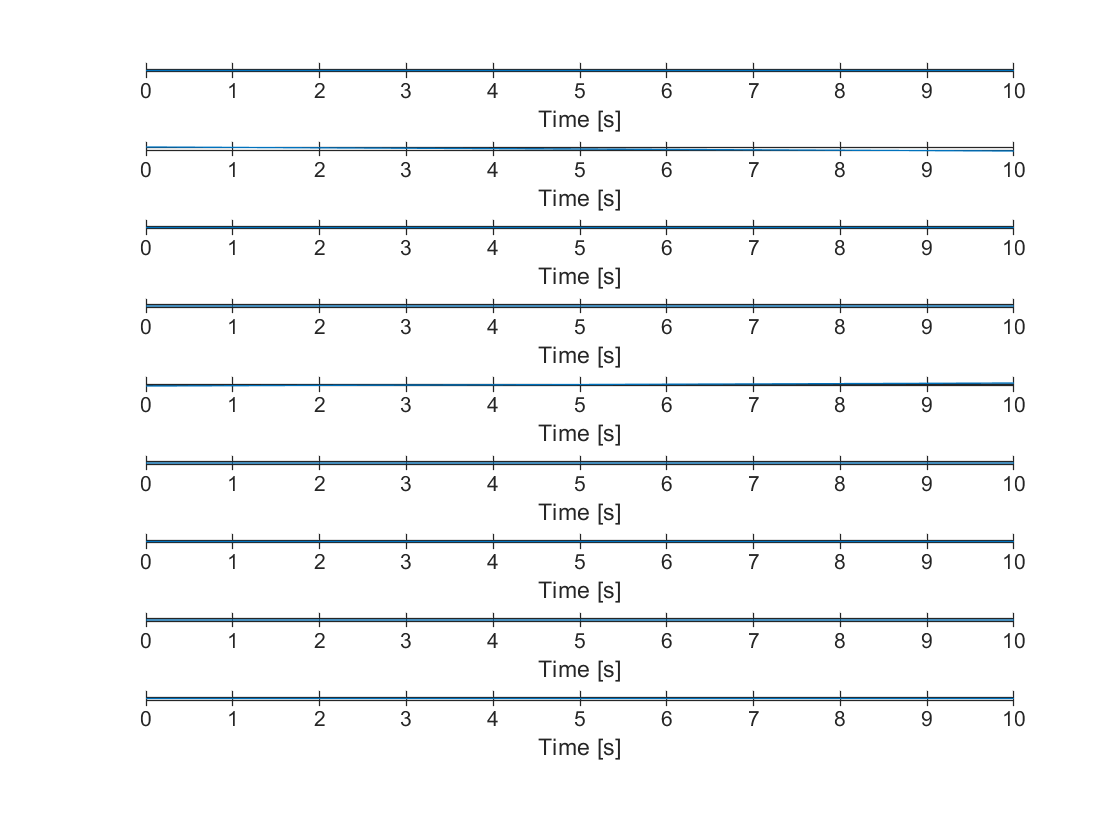

plotMotionNonLin(t5,y5);

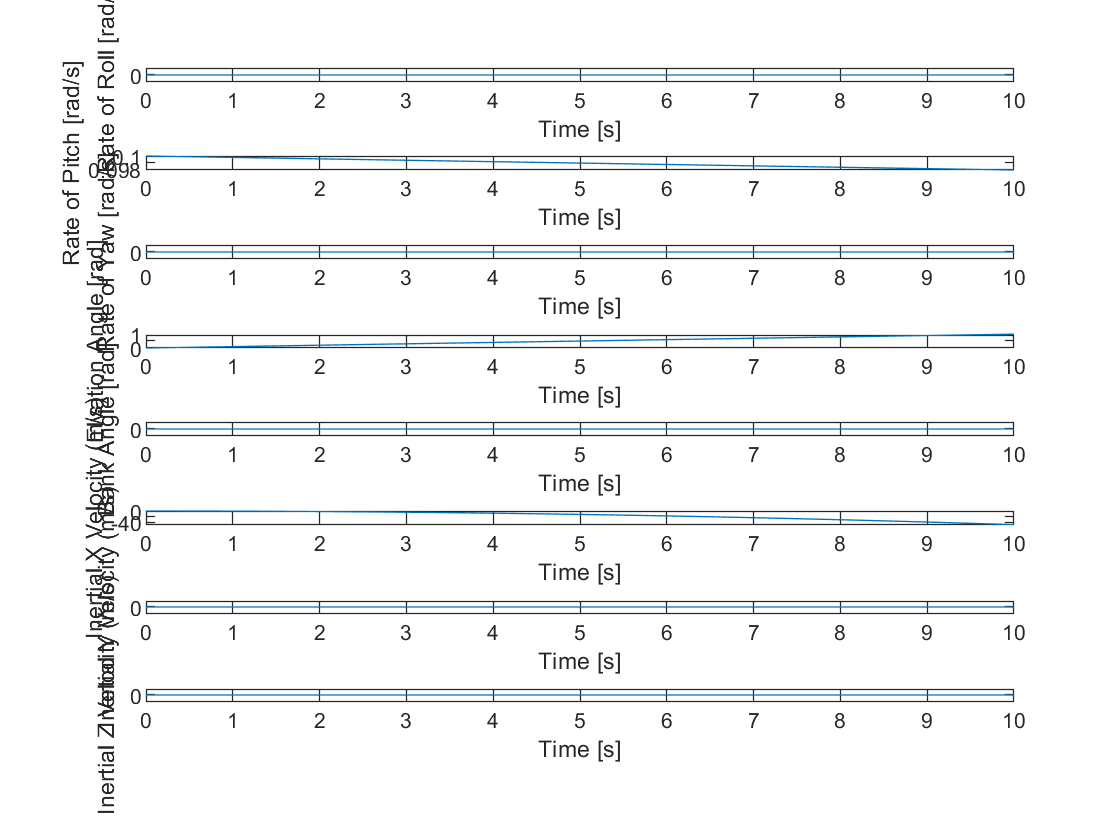

plotMotionLin(tlin5, ylin5);

plotMotionNonLin(t5F,y5F);

## Problem 2.f

### Initialize variables

x = 0; % [m], initial North position
y = 0; % [m], initial East position
z = -5; % [m], initial Down position
inertialVelocity = [0; 0; 0];
psi = 0;
theta = 0;
phi = 0;
p = 0;
q = 0;
r = 0.1;

### Create and Apply Transformation Matrix

L_EB = [cos(theta) * cos(psi), sin(phi) * sin(theta) * cos(psi) - cos(phi) * sin(psi), cos(phi) * sin(theta) * cos(psi) + sin(phi) * sin(psi); ...
        cos(theta) * sin(psi), sin(phi) * sin(theta) * sin(psi) + cos(phi) * cos(psi), cos(phi) * sin(theta) * sin(psi) - sin(phi) * cos(psi); ...
        -sin(theta),           sin(phi) * cos(theta),                                  cos(phi) * cos(theta)];
L_BE = inv(L_EB);
g_body = L_BE * [0; 0; 9.81];
bodyVelocity6 = L_BE * inertialVelocity;
u = bodyVelocity6(1);
v = bodyVelocity6(2);
w = bodyVelocity6(3);

### Preparing for the ODE45

initialState6 = [x y z p q r psi phi theta u v w];
tSpan = [0 10];

### Calling ODE 45

[t6,y6] = ode45('quadcopterSimulation', tSpan, initialState6);
[tlin6,ylin6] = ode45('quadcopterSimulationLin', tSpan, initialState6);
[t6F,y6F] = ode45('quadcopterSimulationNonLinFC', tSpan, initialState4);

### Plotting the results

bodyVelocityFinal = [y6(10); y6(11); y6(12)];
inertialVelocityFinal = L_EB * bodyVelocityFinal;
y6(10) = inertialVelocityFinal(1);
y6(11) = inertialVelocityFinal(2);
y6(12) = inertialVelocityFinal(3);
bodyVelocityFinal = [ylin6(10); ylin6(11); ylin6(12)];
inertialVelocityFinal = L_EB * bodyVelocityFinal;
ylin6(10) = inertialVelocityFinal(1);
ylin6(11) = inertialVelocityFinal(2);
ylin6(12) = inertialVelocityFinal(3);
bodyVelocityFinal = [y6F(10); y6F(11); y6F(12)];
inertialVelocityFinal = L_EB * bodyVelocityFinal;
y6F(10) = inertialVelocityFinal(1);
y6F(11) = inertialVelocityFinal(2);
y6F(12) = inertialVelocityFinal(3);

### +0.1 rad/s Yaw Rate Deviation

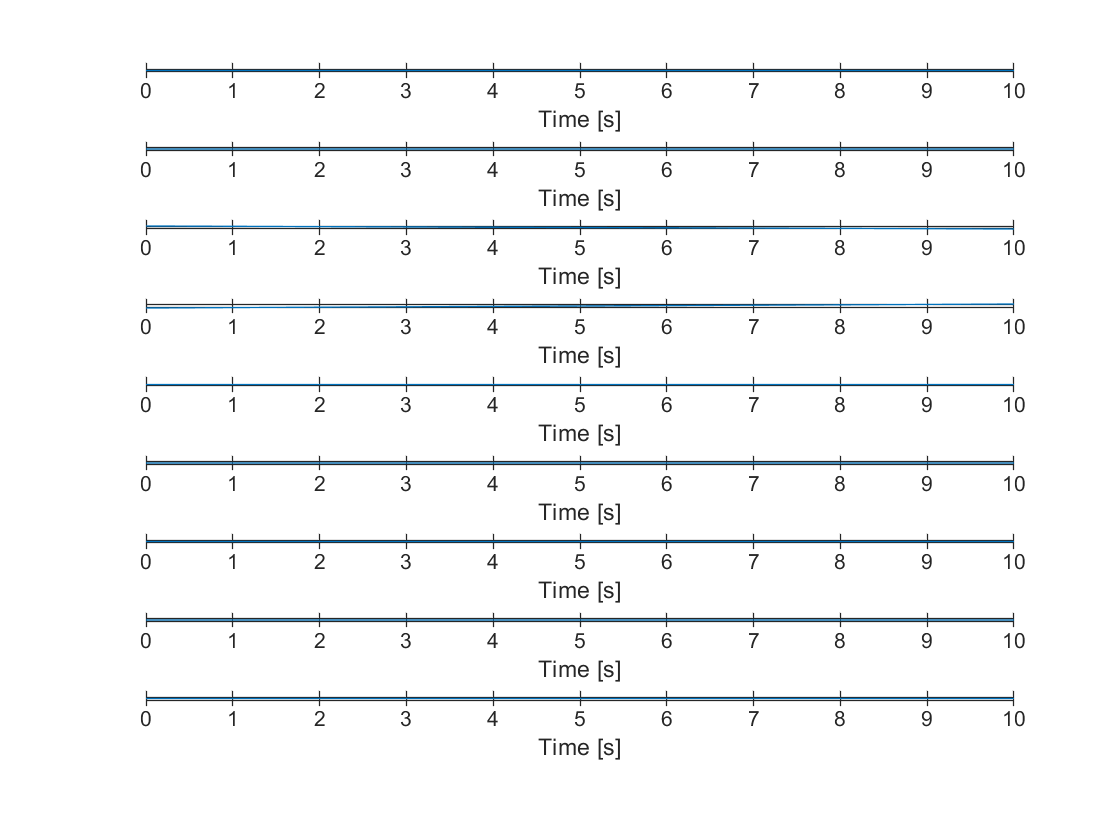

plotMotionNonLin(t6,y6);

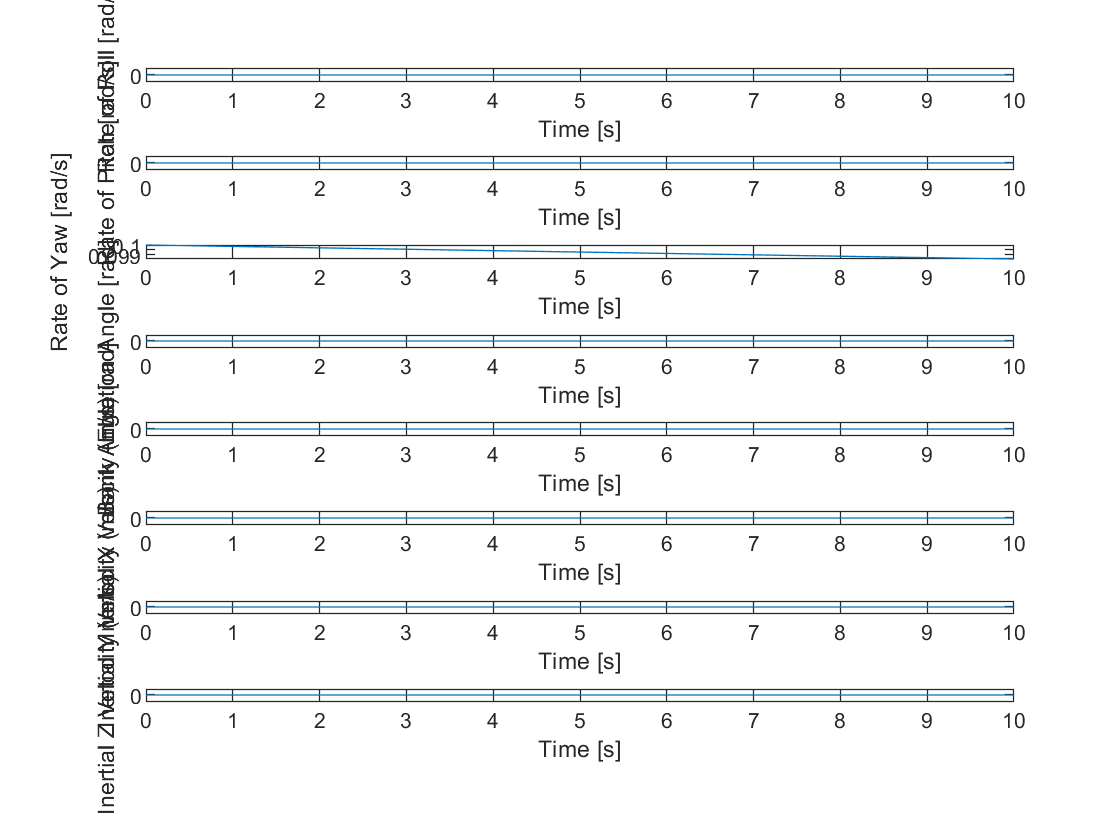

plotMotionLin(tlin6, ylin6);

plotMotionNonLin(t6F,y6F);

## Problem 5

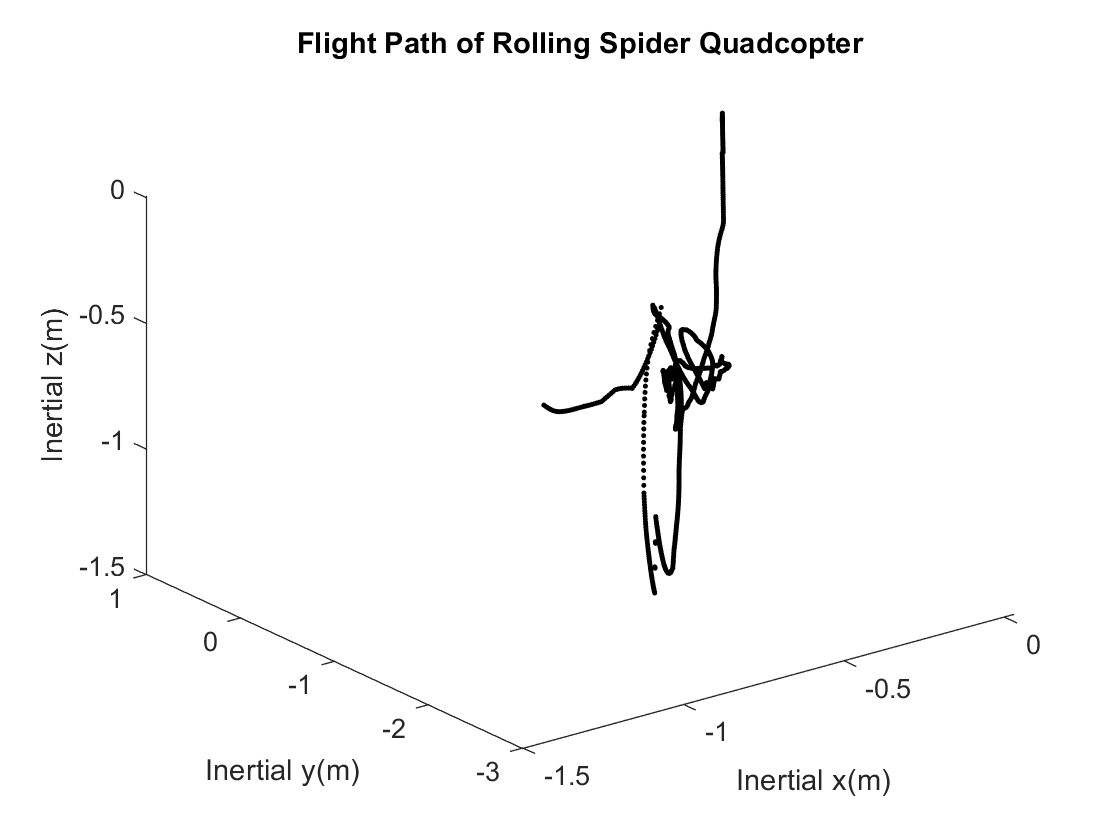

load('RSdata_White_0903.mat');
time=rt_estim.time;
x=rt_estim.signals.values(:,1);
y=rt_estim.signals.values(:,2);
z=rt_estim.signals.values(:,3);
yaw=rt_estim.signals.values(:,4);
pitch=rt_estim.signals.values(:,5);
roll=rt_estim.signals.values(:,6);
Vx=rt_estim.signals.values(:,7);
Vy=rt_estim.signals.values(:,8);
Vz=rt_estim.signals.values(:,9);
p=rt_estim.signals.values(:,10);
q=rt_estim.signals.values(:,11);
r=rt_estim.signals.values(:,12);

figure()
plot3(x,y,z,'.k')
title('Flight Path of Rolling Spider Quadcopter')
xlabel('Inertial x(m)')
ylabel('Inertial y(m)')
zlabel('Inertial z(m)')

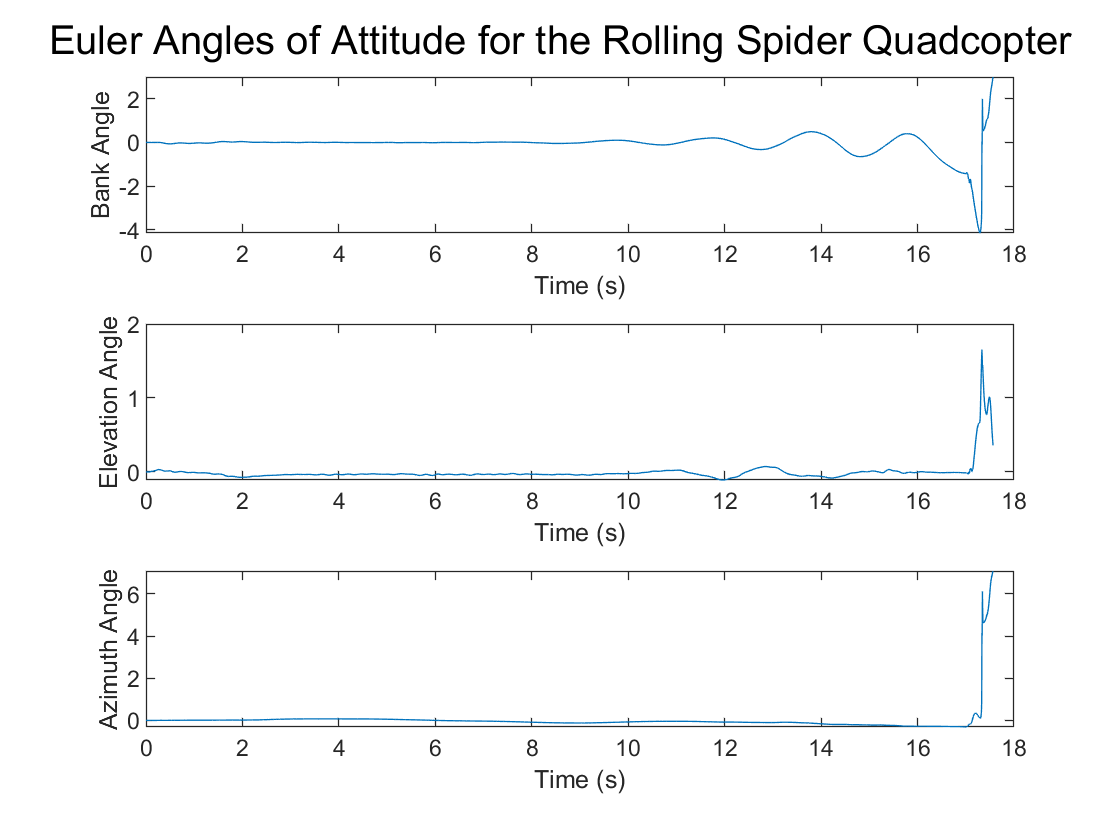


figure()
subplot(3,1,1)
plot(time,roll)
xlabel('Time (s)')
ylabel('Bank Angle')

subplot(3,1,2)
plot(time,pitch)
xlabel('Time (s)')
ylabel('Elevation Angle')

subplot(3,1,3)
plot(time,yaw)
xlabel('Time (s)')
ylabel('Azimuth Angle')

sgtitle('Euler Angles of Attitude for the Rolling Spider Quadcopter')

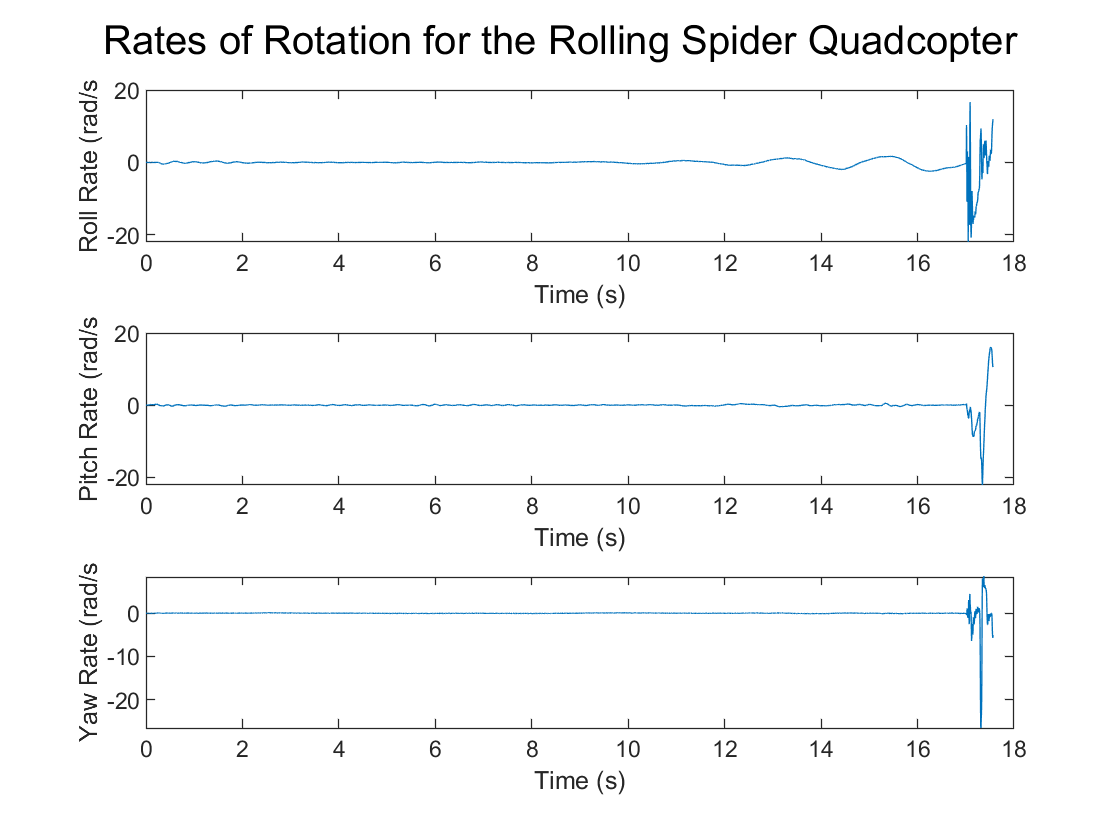


figure()
subplot(3,1,1)
plot(time,p)
xlabel('Time (s)')
ylabel('Roll Rate (rad/s')

subplot(3,1,2)
plot(time,q)
xlabel('Time (s)')
ylabel('Pitch Rate (rad/s')

subplot(3,1,3)
plot(time,r)
xlabel('Time (s)')
ylabel('Yaw Rate (rad/s')

sgtitle('Rates of Rotation for the Rolling Spider Quadcopter')

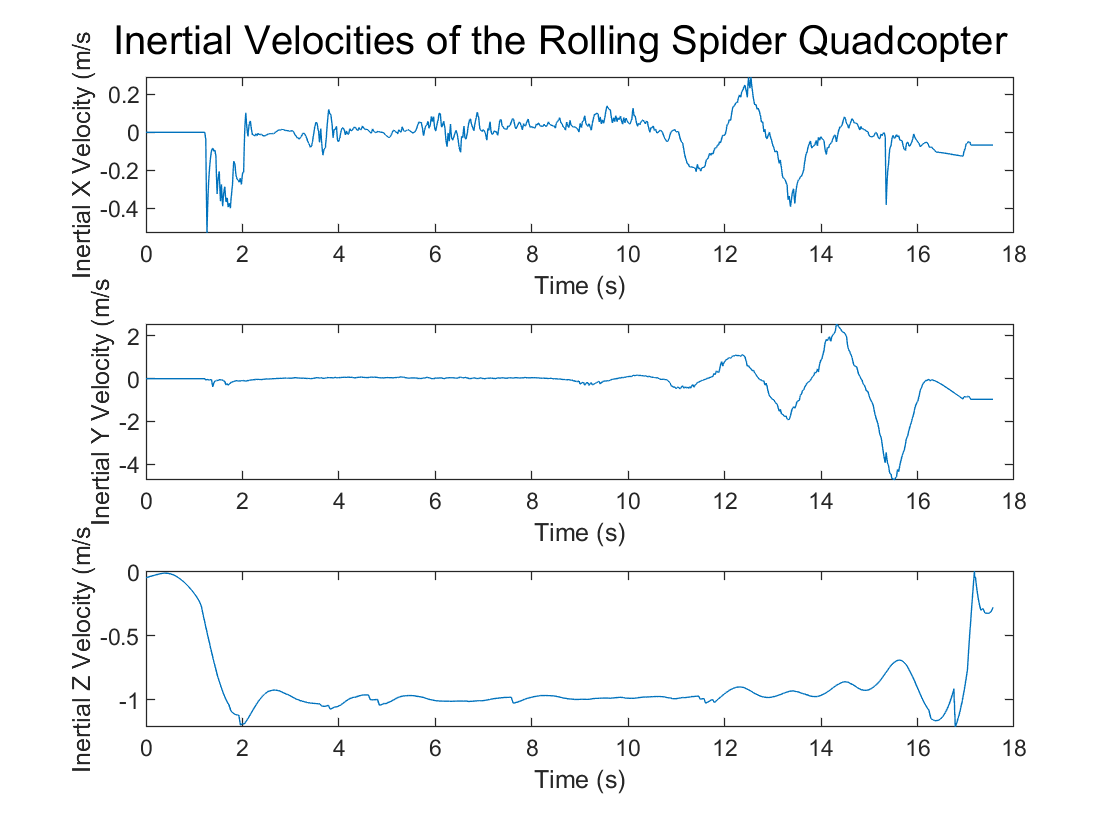


figure()
subplot(3,1,1)
plot(time,Vx)
xlabel('Time (s)')
ylabel('Inertial X Velocity (m/s')

subplot(3,1,2)
plot(time,Vy)
xlabel('Time (s)')
ylabel('Inertial Y Velocity (m/s')

subplot(3,1,3)
plot(time,z)
xlabel('Time (s)')
ylabel('Inertial Z Velocity (m/s')

sgtitle('Inertial Velocities of the Rolling Spider Quadcopter')

plotMotionNonLin plots the nonlinearized differential equations for a quadcopter

Detailed explanation of this function.

function [] = plotMotionNonLin(t, y)

figure;
title("Non-Linearized Responses")
plot3(y(:,1), y(:,2), -y(:,3), "r*");
xlabel("X Displacement");
ylabel("Y Displacement");
zlabel("Z Displacement");
grid on

figure;
subplot(9,1,1);
plot(t, y(:,4));
xlabel("Time [s]");
ylabel("Rate of Roll [rad/s]");

subplot(9,1,2);
plot(t, y(:,5));
xlabel("Time [s]");
ylabel("Rate of Pitch [rad/s]");

subplot(9,1,3);
plot(t, y(:,6));
xlabel("Time [s]");
ylabel("Rate of Yaw [rad/s]");

subplot(9,1,4);
plot(t, y(:,7));
xlabel("Time [s]");
ylabel("Azimuth Angle [rad]");

subplot(9,1,5);
plot(t, y(:,9));
xlabel("Time [s]");
ylabel("Elvation Angle [rad]");

subplot(9,1,6);
plot(t, y(:,8));
xlabel("Time [s]");
ylabel("Bank Angle [rad]");

subplot(9,1,7);
plot(t, y(:,10));
xlabel("Time [s]");
ylabel("Inertial X Velocity (m/s)");

subplot(9,1,8);
plot(t, y(:,11));
xlabel("Time [s]");
ylabel("Inertial Y Velocity (m/s)");

subplot(9,1,9);
plot(t, y(:,12));
xlabel("Time [s]");
ylabel("Inertial Z Velocity (m/s)");

end

plotMotionNonLin plots the nonlinearized differential equations for a quadcopter

Detailed explanation of this function.

function [] = plotMotionLin(t, y)

figure;
title("Linearized Responses")
subplot(8,1,1);
plot(t, y(:,4));
xlabel("Time [s]");
ylabel("Rate of Roll [rad/s]");

subplot(8,1,2);
plot(t, y(:,5));
xlabel("Time [s]");
ylabel("Rate of Pitch [rad/s]");

subplot(8,1,3);
plot(t, y(:,6));
xlabel("Time [s]");
ylabel("Rate of Yaw [rad/s]");

subplot(8,1,4);
plot(t, y(:,9));
xlabel("Time [s]");
ylabel("Elvation Angle [rad]");

subplot(8,1,5);
plot(t, y(:,8));
xlabel("Time [s]");
ylabel("Bank Angle [rad]");

subplot(8,1,6);
plot(t, y(:,10));
xlabel("Time [s]");
ylabel("Inertial X Velocity (m/s)");

subplot(8,1,7);
plot(t, y(:,11));
xlabel("Time [s]");
ylabel("Inertial Y Velocity (m/s)");

subplot(8,1,8);
plot(t, y(:,12));
xlabel("Time [s]");
ylabel("Inertial Z Velocity (m/s)");

end

ODE45 function for the motion of a quadcopter

Detailed explanation of this function.

function derivativeState = quadcopterSimulation(t,State)

Declare global and local constants.

global g I_x I_y I_z m R fb f1 f2 f3 f4 L M N G_body g_body
eta = 1 * 10 ^ (-3); % [N/(m/s)^2], drag per velocity squared
alpha = 2 * 10 ^ (-6); % [N*m/(rad/s)^2], moment per rate of rotation squared
k = 0.0024; % [N*m/N], moment per force of motors

Extract variable from state vector.

x = State(1);
y = State(2);
z = State(3);
p = State(4);
q = State(5);
r = State(6);
psi = State(7);
phi = State(8);
theta = State(9);
u = State(10);
v = State(11);
w = State(12);

Calculate the forces and moments.

Thrust = (-eta * sqrt(u^2 + v^2 + w^2) * w) + (m * g);
f1 = -Thrust / 4;
f2 = -Thrust / 4;
f3 = -Thrust / 4;
f4 = -Thrust / 4;

A_aerodynamic_body = -eta * sqrt(u^2 + v^2 + w^2) * [u; v; w]; % [N], aerodynamic forces on vehicle
A_control_body = [0; 0; f1 + f2 + f3 + f4]; % [N], control forces on vehicle
fb = m * g_body + A_aerodynamic_body + A_control_body; % [N], vector of forces on quadcopter

G_aerodynamic_body = -alpha * sqrt(p^2 + q^2 + r^2) * [p; q; r]; % [N*m], aerodynamic moments on vehicle
L = (R/sqrt(2)) * (f1 + f2 - f3 - f4); % [N*m], control moment
M = (R/sqrt(2)) * (-f1 + f2 + f3 - f4); % [N*m], control moment
N = k * (f1 - f2 + f3 - f4); % [N*m], control moment
G_control_body = [L; M; N]; % [N*m], total control moment
G_body = G_aerodynamic_body + G_control_body + 0; % [N*m], total moments on vehicle

Calculate the derivatives.

xDot = (u * cos(theta) * cos(psi)) + (v * (sin(phi) * sin(theta) * cos(psi) - cos(phi)...
    * sin(psi))) + w * (cos(phi) * sin(theta) * cos(psi) + sin(phi) * sin(psi));
yDot = (u * cos(theta) * sin(psi)) + (v * (sin(phi) * sin(theta) * sin(psi)...
    + cos(phi) * cos(psi))) + w * (cos(phi) * sin(theta) * sin(psi) - sin(phi) * cos(psi));
zDot = (-u * sin(theta))+(v * sin(phi) * cos(theta)) + (w * cos(phi) * cos(theta));

uDot = (fb(1) / m) - (q * w) + (r * v);
vDot = (fb(2) / m) - (r * u) + (p * w);
wDot = (fb(3) / m) - (p * v) + (q * u);

psiDot = (q * sin(phi) + r * cos(phi)) * sec(theta);
phiDot = p + (q * sin(phi) + r * cos(phi)) * tan(theta);
thetaDot =  (q * cos(phi)) - (r * sin(phi));

pDot = (1 / I_x) * (G_body(1) - ((q * r) * (I_z - I_y)));
qDot = (1 / I_y) * (G_body(2) - ((r * p) * (I_x - I_z)));
rDot = (1 / I_z) * (G_body(3) - ((p * q) * (I_y - I_x)));

derivativeState = [xDot yDot zDot pDot qDot rDot psiDot phiDot thetaDot uDot vDot wDot].';

end


ODE45 function for the motion of a quadcopter

Detailed explanation of this function.

function derivativeState = quadcopterSimulationLin(t,State)

Declare global and local constants.

global g I_x I_y I_z m R fb f1 f2 f3 f4 L M N G_body g_body
eta = 1 * 10 ^ (-3); % [N/(m/s)^2], drag per velocity squared
alpha = 2 * 10 ^ (-6); % [N*m/(rad/s)^2], moment per rate of rotation squared
k = 0.0024; % [N*m/N], moment per force of motors

Extract variable from state vector.

x = State(1);
y = State(2);
z = State(3);
p = State(4);
q = State(5);
r = State(6);
psi = State(7);
phi = State(8);
theta = State(9);
u = State(10);
v = State(11);
w = State(12);

Calculate the forces and moments.

Thrust = (-eta * sqrt(u^2 + v^2 + w^2) * w) + (m * g);
f1 = -Thrust / 4;
f2 = -Thrust / 4;
f3 = -Thrust / 4;
f4 = -Thrust / 4;

A_aerodynamic_body = -eta * sqrt(u^2 + v^2 + w^2) * [u; v; w]; % [N], aerodynamic forces on vehicle
A_control_body = [0; 0; f1 + f2 + f3 + f4]; % [N], control forces on vehicle
fb = m * g_body + A_aerodynamic_body + A_control_body; % [N], vector of forces on quadcopter

G_aerodynamic_body = -alpha * sqrt(p^2 + q^2 + r^2) * [p; q; r]; % [N*m], aerodynamic moments on vehicle
L = (R/sqrt(2)) * (f1 + f2 - f3 - f4); % [N*m], control moment
M = (R/sqrt(2)) * (-f1 + f2 + f3 - f4); % [N*m], control moment
N = k * (f1 - f2 + f3 - f4); % [N*m], control moment
G_control_body = [L; M; N]; % [N*m], total control moment
G_body = G_aerodynamic_body + G_control_body + 0; % [N*m], total moments on vehicle

Calculate the derivatives.

xDot = (u * cos(theta) * cos(psi)) + (v * (sin(phi) * sin(theta) * cos(psi) - cos(phi)...
    * sin(psi))) + w * (cos(phi) * sin(theta) * cos(psi) + sin(phi) * sin(psi));
yDot = (u * cos(theta) * sin(psi)) + (v * (sin(phi) * sin(theta) * sin(psi)...
    + cos(phi) * cos(psi))) + w * (cos(phi) * sin(theta) * sin(psi) - sin(phi) * cos(psi));
zDot = (-u * sin(theta))+(v * sin(phi) * cos(theta)) + (w * cos(phi) * cos(theta));

uDot = -g * theta;
vDot = g * phi;
wDot = 0;

psiDot = (q * sin(phi) + r * cos(phi)) * sec(theta);
phiDot = p;
thetaDot = q;

pDot = (1 / I_x) * (G_body(1));
qDot = (1 / I_y) * (G_body(2));
rDot = (1 / I_z) * (G_body(3));

derivativeState = [xDot yDot zDot pDot qDot rDot psiDot phiDot thetaDot uDot vDot wDot].';

end


ODE45 function for the motion of a quadcopter

Detailed explanation of this function.

function derivativeState = quadcopterSimulationNonLinFC(t,State)

Declare global and local constants.

global g I_x I_y I_z m R fb f1 f2 f3 f4 L M N G_body g_body
eta = 1 * 10 ^ (-3); % [N/(m/s)^2], drag per velocity squared
alpha = 2 * 10 ^ (-6); % [N*m/(rad/s)^2], moment per rate of rotation squared
k = 0.0024; % [N*m/N], moment per force of motors
Fc = 0.004;

Extract variable from state vector.

x = State(1);
y = State(2);
z = State(3);
p = State(4);
q = State(5);
r = State(6);
psi = State(7);
phi = State(8);
theta = State(9);
u = State(10);
v = State(11);
w = State(12);

Calculate the forces and moments.

Thrust = (-eta * sqrt(u^2 + v^2 + w^2) * w) + (m * g);
f1 = -Thrust / 4;
f2 = -Thrust / 4;
f3 = -Thrust / 4;
f4 = -Thrust / 4;

A_aerodynamic_body = -eta * sqrt(u^2 + v^2 + w^2) * [u; v; w]; % [N], aerodynamic forces on vehicle
A_control_body = [0; 0; f1 + f2 + f3 + f4]; % [N], control forces on vehicle
fb = m * g_body + A_aerodynamic_body + A_control_body; % [N], vector of forces on quadcopter

G_aerodynamic_body = -alpha * sqrt(p^2 + q^2 + r^2) * [p; q; r]; % [N*m], aerodynamic moments on vehicle
L = (R/sqrt(2)) * (f1 + f2 - f3 - f4) - Fc * p; % [N*m], control moment
M = (R/sqrt(2)) * (-f1 + f2 + f3 - f4) - Fc * q; % [N*m], control moment
N = k * (f1 - f2 + f3 - f4) - Fc * r; % [N*m], control moment
G_control_body = [L; M; N]; % [N*m], total control moment
G_body = G_aerodynamic_body + G_control_body + 0; % [N*m], total moments on vehicle

Calculate the derivatives.

xDot = (u * cos(theta) * cos(psi)) + (v * (sin(phi) * sin(theta) * cos(psi) - cos(phi)...
    * sin(psi))) + w * (cos(phi) * sin(theta) * cos(psi) + sin(phi) * sin(psi));
yDot = (u * cos(theta) * sin(psi)) + (v * (sin(phi) * sin(theta) * sin(psi)...
    + cos(phi) * cos(psi))) + w * (cos(phi) * sin(theta) * sin(psi) - sin(phi) * cos(psi));
zDot = (-u * sin(theta))+(v * sin(phi) * cos(theta)) + (w * cos(phi) * cos(theta));

uDot = (fb(1) / m) - (q * w) + (r * v);
vDot = (fb(2) / m) - (r * u) + (p * w);
wDot = (fb(3) / m) - (p * v) + (q * u);

psiDot = (q * sin(phi) + r * cos(phi)) * sec(theta);
phiDot = p + (q * sin(phi) + r * cos(phi)) * tan(theta);
thetaDot =  (q * cos(phi)) - (r * sin(phi));

pDot = (1 / I_x) * (G_body(1) - ((q * r) * (I_z - I_y)));
qDot = (1 / I_y) * (G_body(2) - ((r * p) * (I_x - I_z)));
rDot = (1 / I_z) * (G_body(3) - ((p * q) * (I_y - I_x)));

derivativeState = [xDot yDot zDot pDot qDot rDot psiDot phiDot thetaDot uDot vDot wDot].';

end

